# Full Wave Simulator

Converts LTSPICE .txt files to a MATLAB Matrix and plots

To be used after GANFET_FullWaveSim_v1.mlx

## Directory and Internal Libraries/Functions

Sets paths easily to run, calling functions that import different data types

computer = "PC"

computer = "PC"

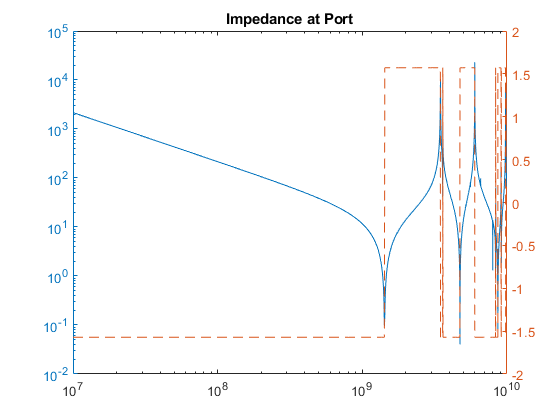

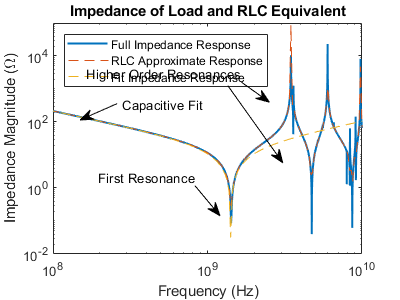

C_eff = 7.3984e-12

L_eff = 1.6980e-09

if (strcmp(computer, 'PC')) % PC
    %cd 'G:\My Drive\Code\LTSpice\200630 xGAN xGEM Load Responses V0';
    cd 'C:\Users\johns\Documents\Github\Gated-Mirror_xGANxSCAxGEM\200801 xGAN Full Module v1'
    addpath( 'G:\My Drive\Code\LTSpice\200825 xGAN xGEM Load Responses V1\', ...  % LT Spice output response
        'C:\Users\johns\Documents\Github\Gated-Mirror_xGANxSCAxGEM\200801 xGAN Full Module v1',...
        'C:\Users\johns\Documents\Github\QEM-MATLAB\Data Converters\LTSpice_Converter', ... % LT Spice reader from Github
        'C:\Users\johns\Documents\Github\QEM-MATLAB', ...    % Access to generic libraries
        'G:\My Drive\Code\COMSOL\xGAN Gated Mirror Sims\Export'); %new comsol stuff
    
elseif (strcmp(computer, 'Mac'))
    %cd 'C:\Users\johns\Documents\Github\QEM-MATLAB\Data Converters\LTSpice_Converter'
    addpath('/Volumes/GoogleDrive/My Drive/Code/Github Failed MATLAB 200807/QEM-MATLAB/Data Converters/LTSpice_Converter', ...
        '/Volumes/GoogleDrive/My Drive/Code/Github Failed MATLAB 200807/QEM-MATLAB', ...
        '/Volumes/GoogleDrive/My Drive/Code/Github Failed MATLAB 200807/Gated-Mirror_xGANxSCAxGEM/200801 xGAN Full Module v1');
end

load('ImpVariables.mat')

## Import Point Transfer Function 

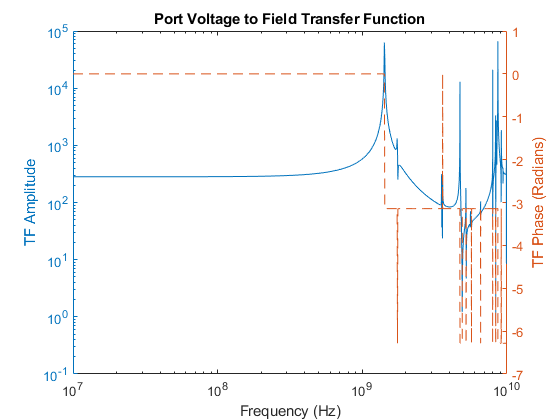

filename='Kimball_TF.txt';
makeSymmetric = 1;
[rawTF, symTF] = ImportCOMSOL_TF(filename, port.v, makeSymmetric);

clf;
% Look at transfer Function
yyaxis left
loglog(rawTF.freq,abs(rawTF.fieldTF)); ylabel("TF Amplitude");
yyaxis right
semilogx(rawTF.freq, unwrap(angle(rawTF.fieldTF)),'LineStyle',"--"); ylabel("TF Phase (Radians)"); xlabel("Frequency (Hz)");
title("Port Voltage to Field Transfer Function");
hold off

## Import Integral Transfer Function 

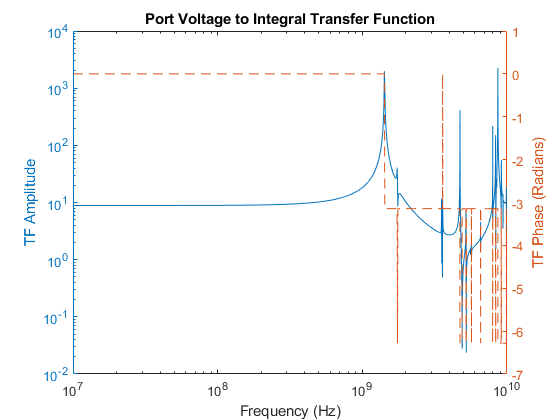

filename='IntegralExport.txt';
makeSymmetric = 1;
[rawTF, symTF] = ImportCOMSOL_TF(filename, port.v, makeSymmetric);

clf;
% Look at transfer Function
yyaxis left
loglog(rawTF.freq,abs(rawTF.fieldTF)); ylabel("TF Amplitude");
yyaxis right
semilogx(rawTF.freq, unwrap(angle(rawTF.fieldTF)),'LineStyle',"--"); ylabel("TF Phase (Radians)"); xlabel("Frequency (Hz)");
title("Port Voltage to Integral Transfer Function");
hold off

## Time Domain Constant step exporter

Takes data from batch files in LTSpice and exports

name = '200825 xGAN Kimball Circuit Resetting.txt';
timeRes = 1/20e9; % 20GHz total BW (10Ghz positive)
interpMethod = 'linear'; %pchip linear
[stepR,interpTime, interpVoltAll] = ImportLTSpiceSweep(name, timeRes, interpMethod);
% ADD LTSPICE SIM NOTES

% Plots out result read from file to check
figure()
plot(interpTime/c.nano, interpVoltAll, "LineWidth", 1.5); xlabel('Time (ns)'); ylabel('Voltage (V)'); title('Port Voltage with Varying Resistances')
rNames = string(stepR);
legend('R=' + rNames +'\Omega')
%xlim([0 10])
save("200825 xGAN Kimball Circuit Resetting.mat", "stepR", "interpTime", "interpVoltAll");

## Generate and Plot LTSpice Output FT

% clf;

% [time, signal, freq, fftSignal] = inputFunction('gEdge', 1/20e9, 10*c.mega,  interpTime, interpVoltAll(resIndex,:),100e15);
% plot(time/c.nano, signal); xlabel("Time (ns)"); ylabel("Voltage (V)"); title("LTSpice Port Voltage")
% %xlim([0,10])
% 
% %Compares steps
% % for resIndexTemp = 1:9
% %     [time, signal, freq, fftSignal] = inputFunction('Custom', 1/20e9, 10*c.mega,  interpTime, interpVoltAll(resIndexTemp,:));
% %     loglog(freq((end-1)/2+1:end), abs(fftSignal(2:(end+1)/2+1)/abs(fftSignal(1)))); 
% %     xlabel("Frequency"); ylabel("Amplitude"); title('Pulse in Frequency Domain')
% %     hold on
% % end
% % xlim([5e8 1e10])
% % hold off


## Combine and Plot Output

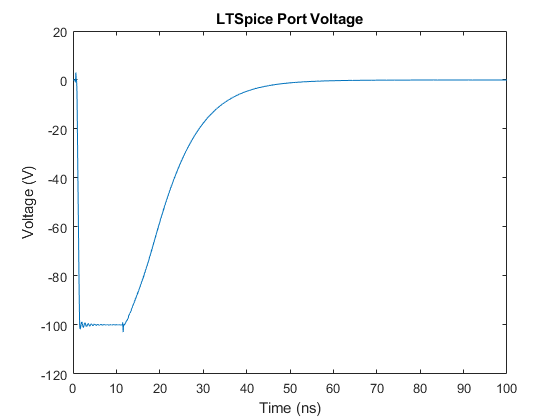

clf
resIndex = 1;
%tiledlayout(2,2);
stepR(resIndex);
[time, signal, freq, fftSignal] = inputFunction('Custom', 1/20e9, 10*c.mega,  interpTime, interpVoltAll(resIndex,:),0, 0);
% Plot Original Time
plot(time/c.nano, signal); xlabel("Time (ns)"); ylabel("Voltage (V)"); title("LTSpice Port Voltage")

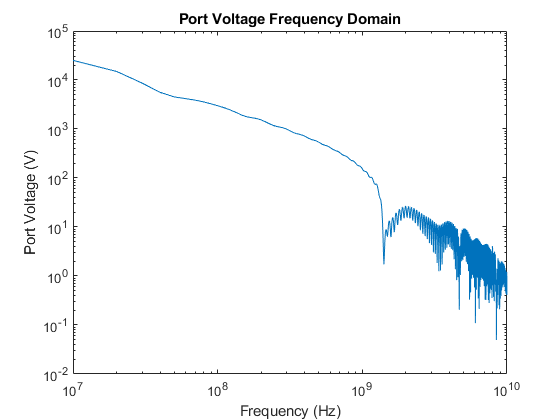


% Plot FFT Original
loglog(freq((end-1)/2+1:end), abs(fftSignal(2:(end+1)/2+1))); title('Port Voltage Frequency Domain'); xlabel('Frequency (Hz)'); ylabel('Port Voltage (V)')

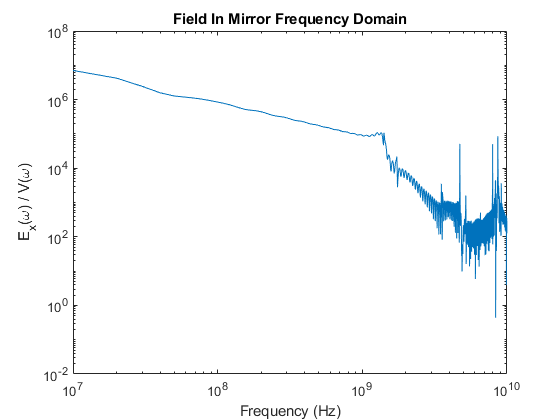


% Plot Mixed Signal
outputFFT = fftSignal.*symTF.fieldTF;
loglog(freq((end-1)/2+1:end), abs(outputFFT(2:(end+1)/2+1))); title('Field In Mirror Frequency Domain'); xlabel('Frequency (Hz)'); ylabel('E_x(\omega) / V(\omega)')

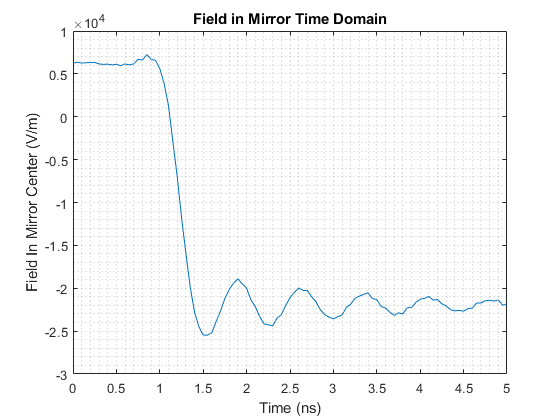


% Plot Final Result
outputSignal = ifft(outputFFT); 
plot(time/c.nano, outputSignal);%, [-50 50], [0.5 0.5], '--', [-50 50], [0.005 0.005], '--');
title('Field in Mirror Time Domain'); xlabel("Time (ns)"); ylabel("Field In Mirror Center (V/m)");
grid minor;
xlim([0,5])

## Plot Multiple Outputs

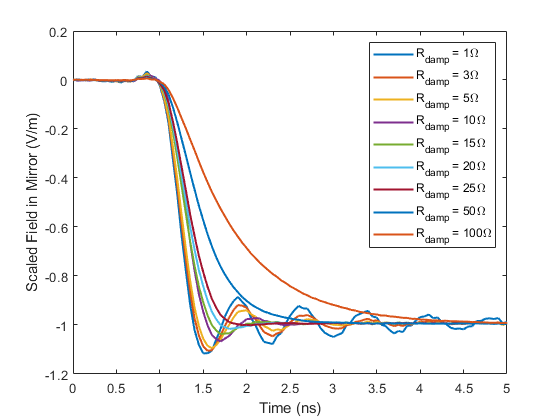

%Compares steps
clf;
%SelectedTraces = [1, 10, 25, 50]
%outputSignalAll = zeros(9,2001);
for resIndexTemp = 1:9
    [time, signal, freq, fftSignal] = inputFunction('Custom', 1/20e9, 10*c.mega,  interpTime, interpVoltAll(resIndexTemp,:), 0, 0);
    
    outputFFT = fftSignal.*symTF.fieldTF;
    outputSignalAll(resIndexTemp,:) = ifft(outputFFT); 
end
outputSignalRescaled = (outputSignalAll-outputSignalAll(1,1))/outputSignalAll(1,1)*0.22;
plot(time/c.nano, outputSignalRescaled, 'LineWidth',1.5);
%title('Field in Mirror Time Domain'); 
xlabel("Time (ns)"); ylabel("Scaled Field in Mirror (V/m)");
legend('R_{damp} = ' + rNames +'\Omega')
%legend("Ideal Gaussian Response")
xlim([0,5])

%ylim([-1.1, -0.9])


## Plot Step Function

% clf
% stepR(resIndex);
% [time, signal, freq, fftSignal] = inputFunction('Heaviside', 1/20e9, 10*c.mega,  interpTime, interpVoltAll(resIndex,:),1000, -1030);
% % Plot Original Time
% plot(time/c.nano, signal); xlabel("Time (ns)"); ylabel("Voltage (V)"); title("Ideal Port Voltage"); xlim([0 5])
% 
% % Plot FFT Original
% % loglog(freq((end-1)/2+1:end), abs(fftSignal(2:(end+1)/2+1))); title('Port Voltage Frequency Domain'); xlabel('Frequency (Hz)'); ylabel('Port Voltage (V)')
% 
% % Plot Mixed Signal
% outputFFT = fftSignal.*symTF.fieldTF;
% %loglog(freq((end-1)/2+1:end), abs(outputFFT(2:(end+1)/2+1))); title('Field In Mirror Frequency Domain'); xlabel('Frequency (Hz)'); ylabel('E_x(\omega) / V(\omega)')
% 
% % Plot Final Result
% outputSignal = ifft(outputFFT); 
% outputSignalRescaled = ((outputSignal+180)/320); %(outputSignal-outputSignal(1,1))/outputSignal(1,1)/2;
% plot(time/c.nano, outputSignalRescaled);%, [-50 50], [0.5 0.5], '--', [-50 50], [0.005 0.005], '--');
% title('Field in Mirror Time Domain'); xlabel("Time (ns)"); ylabel("Field In Mirror Center (V/m)");
% xlim([0,5])
% %erfOutput = outputSignalRescaled-1;
% %erfTime = time;
% %ylim([0 0.01])

## Plot Step with Error Function

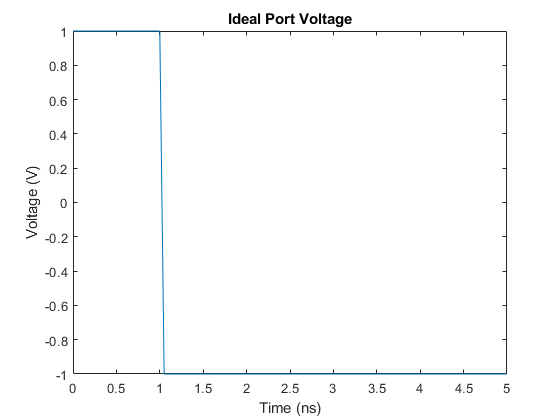

clf
[time, signal, freq, fftSignal] = inputFunction('ErrorFn', 1/20e9, 10*c.mega,  interpTime, interpVoltAll(resIndex,:),1000, -880);
% Plot Original Time
plot(time/c.nano, signal); xlabel("Time (ns)"); ylabel("Voltage (V)"); title("Ideal Port Voltage"); xlim([0 5])

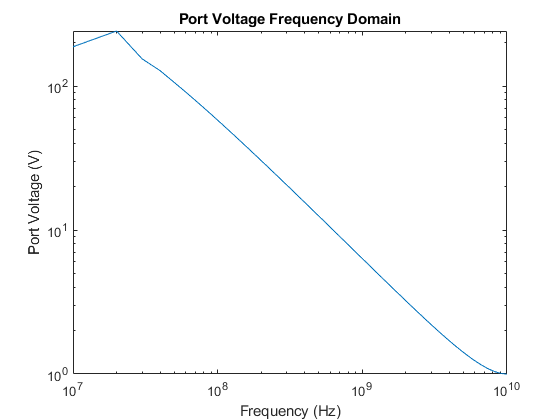


% Plot FFT Original
loglog(freq((end-1)/2+1:end), abs(fftSignal(2:(end+1)/2+1))); title('Port Voltage Frequency Domain'); xlabel('Frequency (Hz)'); ylabel('Port Voltage (V)')

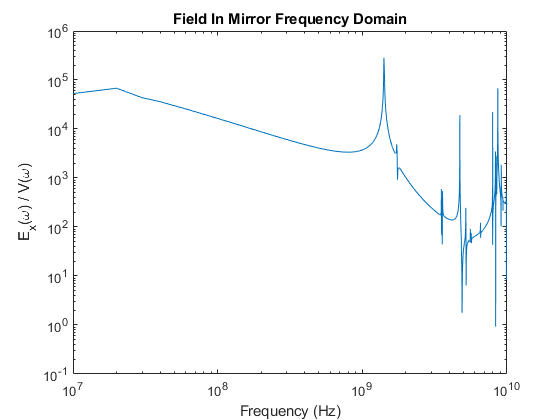


% Plot Mixed Signal
outputFFT = fftSignal.*symTF.fieldTF;
loglog(freq((end-1)/2+1:end), abs(outputFFT(2:(end+1)/2+1))); title('Field In Mirror Frequency Domain'); xlabel('Frequency (Hz)'); ylabel('E_x(\omega) / V(\omega)')

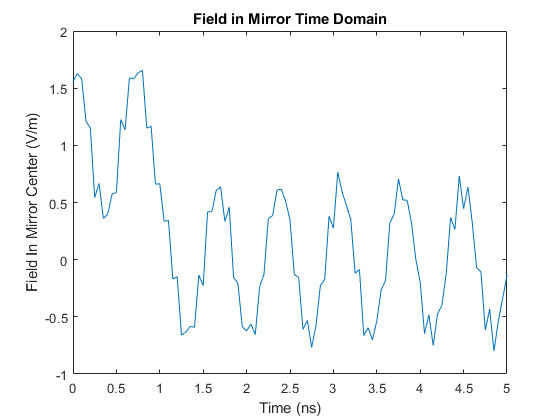


% Plot Final Result
outputSignal = ifft(outputFFT); 
scaleShift = 270;
outputSignalRescaled_fastest = ((outputSignal+scaleShift)/(2*scaleShift)); %(outputSignal-outputSignal(1,1))/outputSignal(1,1)/2;
plot(time/c.nano, outputSignalRescaled_fastest);%, [-50 50], [0.5 0.5], '--', [-50 50], [0.005 0.005], '--');
title('Field in Mirror Time Domain'); xlabel("Time (ns)"); ylabel("Field In Mirror Center (V/m)");
xlim([0,5])

%erfOutput = outputSignalRescaled-1;
%erfTime = time;
%ylim([0 0.01])


## Plot Slow Error Function (Ideal) Response

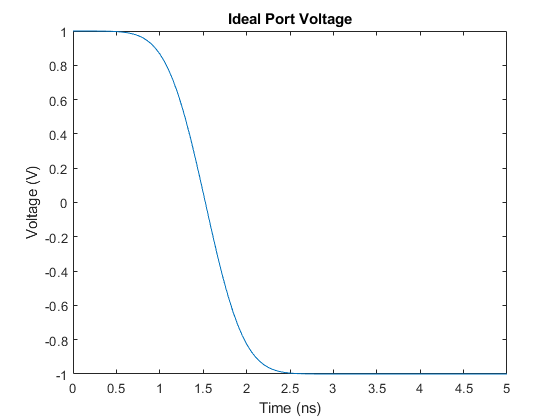

clf

[time, signal, freq, fftSignal] = inputFunction('ErrorFn', 1/20e9, 10*c.mega,  interpTime, interpVoltAll(resIndex,:),10.05, -870);
% Plot Original Time
plot(time/c.nano, signal); xlabel("Time (ns)"); ylabel("Voltage (V)"); title("Ideal Port Voltage"); xlim([0 5])

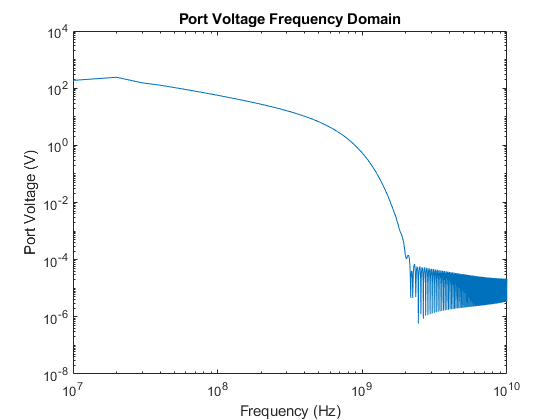


% Plot FFT Original
loglog(freq((end-1)/2+1:end), abs(fftSignal(2:(end+1)/2+1))); title('Port Voltage Frequency Domain'); xlabel('Frequency (Hz)'); ylabel('Port Voltage (V)')

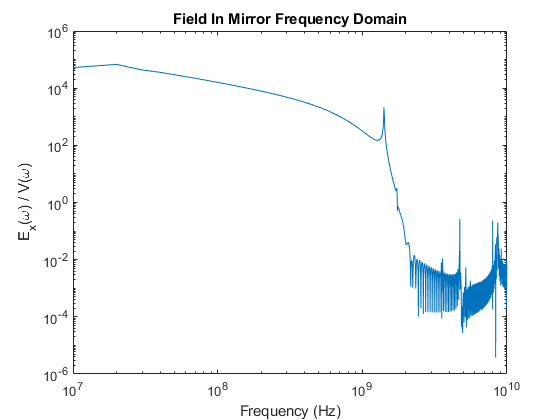


% Plot Mixed Signal
outputFFT = fftSignal.*symTF.fieldTF;
loglog(freq((end-1)/2+1:end), abs(outputFFT(2:(end+1)/2+1))); title('Field In Mirror Frequency Domain'); xlabel('Frequency (Hz)'); ylabel('E_x(\omega) / V(\omega)')

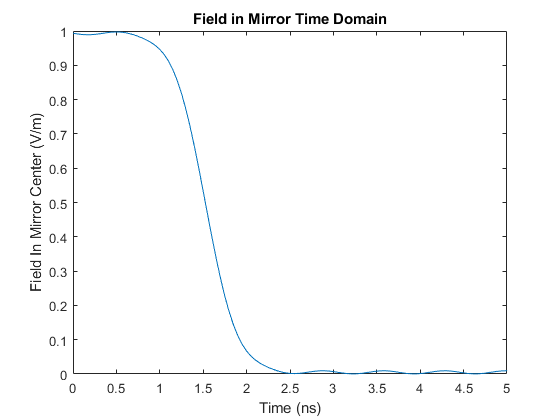


% Plot Final Result
outputSignal = ifft(outputFFT); 
outputSignalRescaled_medium = ((outputSignal+288)/570- 0.006); %(outputSignal-outputSignal(1,1))/outputSignal(1,1)/2;
plot(time/c.nano, outputSignalRescaled_medium);%, [-50 50], [0.5 0.5], '--', [-50 50], [0.005 0.005], '--');
title('Field in Mirror Time Domain'); xlabel("Time (ns)"); ylabel("Field In Mirror Center (V/m)");
xlim([0,5])

%erfOutput = outputSignalRescaled-1;
%erfTime = time;
%ylim([0 0.01])



## Gaussian Filter Response

## Plot Slow Error Function (Ideal) Response

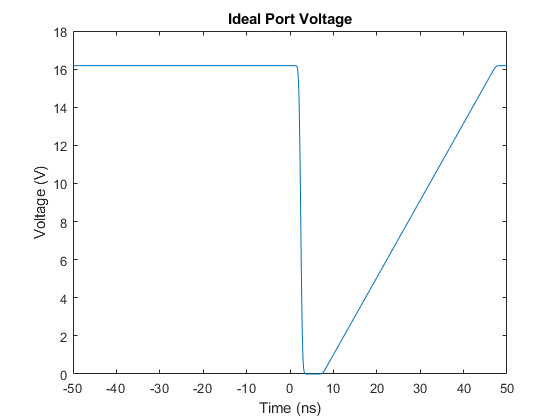

clf

[time, signal, freq, fftSignal] = inputFunction('GaussFilt', 1/20e9, 10*c.mega,  interpTime, interpVoltAll(resIndex,:),1.2*1e4, -150);
% Plot Original Time
plot(time/c.nano, signal); xlabel("Time (ns)"); ylabel("Voltage (V)"); title("Ideal Port Voltage"); %xlim([0 5])

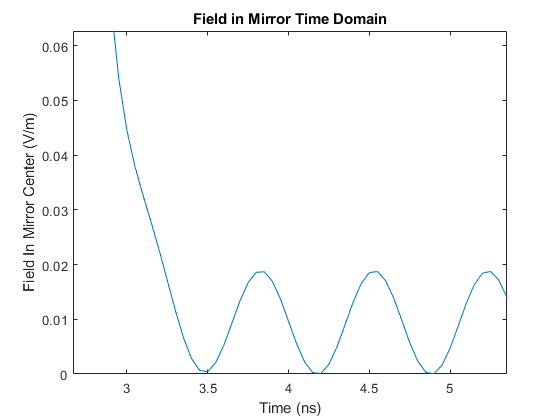


% Plot FFT Original
%loglog(freq((end-1)/2+1:end), abs(fftSignal(2:(end+1)/2+1))); title('Port Voltage Frequency Domain'); xlabel('Frequency (Hz)'); ylabel('Port Voltage (V)')

% Plot Mixed Signal
outputFFT = fftSignal.*symTF.fieldTF;
%loglog(freq((end-1)/2+1:end), abs(outputFFT(2:(end+1)/2+1))); title('Field In Mirror Frequency Domain'); xlabel('Frequency (Hz)'); ylabel('E_x(\omega) / V(\omega)')

% Plot Final Result
outputSignal = ifft(outputFFT); 
outputSignalRescaled_gfilt = (rescale(outputSignal)); %(outputSignal-outputSignal(1,1))/outputSignal(1,1)/2;
plot(time/c.nano, outputSignalRescaled_gfilt);%, [-50 50], [0.5 0.5], '--', [-50 50], [0.005 0.005], '--');
title('Field in Mirror Time Domain'); xlabel("Time (ns)"); ylabel("Field In Mirror Center (V/m)");
xlim([0,5])

## Combine into final plot

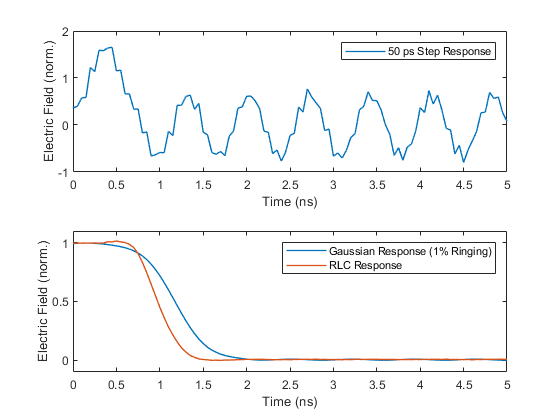

clf;
tiledlayout(2,1)
nexttile
plot( ...
    time/c.nano, circshift(outputSignalRescaled_fastest, -7), "LineWidth",1)
xlim([0 5]);
xlabel('Time (ns)')
ylabel('Electric Field (norm.)')
legend('50 ps Step Response')

nexttile
plot( ...
    time/c.nano, circshift(outputSignalRescaled_medium,-7), ...
    time/c.nano, circshift((outputSignalRescaled(7, :)+1), 993), ...
    'linewidth', 1)%, time/c.nano, outputSignalRescaled_gfilt);
xlim([0 5]);
ylim([-0.1 1.1])
xlabel('Time (ns)')
ylabel('Electric Field (norm.)')
legend('Gaussian Response (1% Ringing)', 'RLC Response', '50 ps Step Response')